# APMA 2501 - Programming in R & MATLAB: MATLAB Unit 3

## **Conducting Loop & Iterations**

- Topic 1: Predator Prey with Iteration

- Topic 2: Pocket Change with Iteration

What we will do today:

- Review for and while loops

- Continuous vs discretized

- Numerical integration: forward Euler's method

- Flow control using for loop

## **MATLAB Copilot topic #2: Generate or Modify Code**

MATLAB Copilot supports users by generating new MATLAB code and modifying existing code based on MathWorks documentation and code examples. It can help complete functions, refactor or optimize code, fix errors, and adapt scripts to new requirements, making the coding process faster and more intuitive. By integrating directly into the MATLAB environment, MATLAB Copilot allows users to focus more on problem-solving and analysis, removing unnecessary time wasted for debugging syntax errors, and minor coding mistakes. 

Key tips and advice for generating or modifying code:

- Don't ask Copilot to code whole projects. Split the task up into smaller chunks.

- Be descriptive in what you want from the code - better context results in better output from Copilot.

- You can further ask Copilot questions about the output. Do not simply use code without understanding the underlying features.

## Topic 1: Predator Prey with Iteration

The populations of Canadian lynx and snowshoe hare observed from the pelt-trading records of the Hudson Bay Company over almost a century

- Oscillating behavior of these two populations

- Predator peak lags slightly behind prey peak

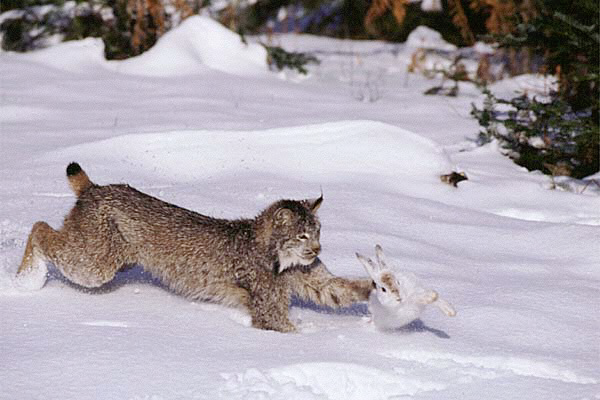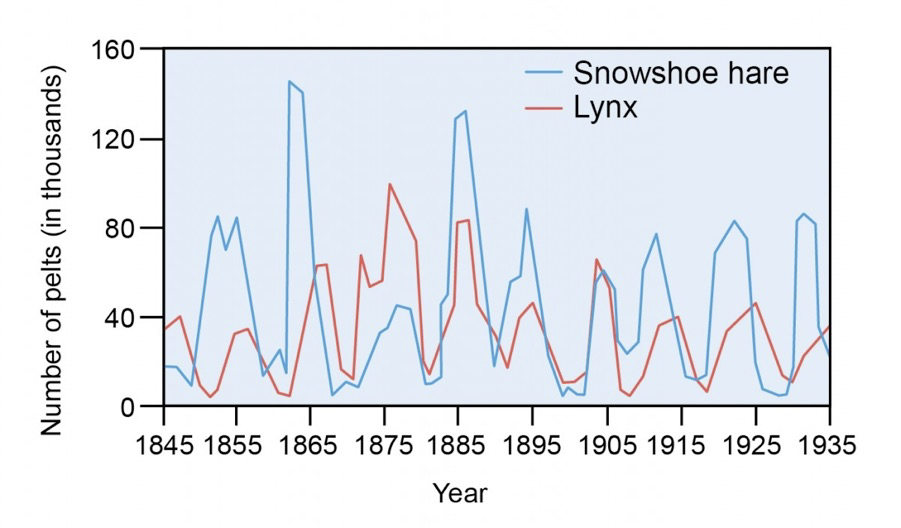

### Mathematical Model

Simplest mathematical model: Lotka–Volterra equations by Italian mathematician Vito Volterra and American mathematical biologist Alfred Lotka.

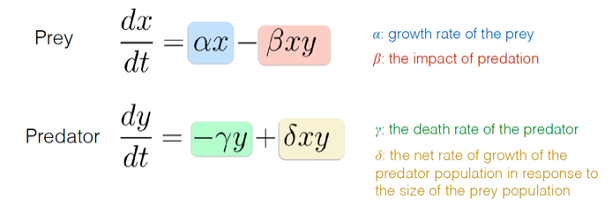

### Assumptions of Lotka–Volterra Equation

- The prey population finds ample food at all times.

- The food supply of the predator population depends entirely on the size of the prey population.

- The rate of change of population is proportional to its size.

- During the process, the environment does not change in favor of one species and the genetic adaptation is sufficiently slow.

- Predators have limitless appetite.

Note: Predator-prey model applied to epidemics, combustion theory, economics…

### Numerical Method

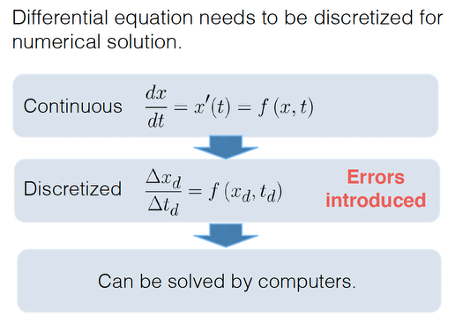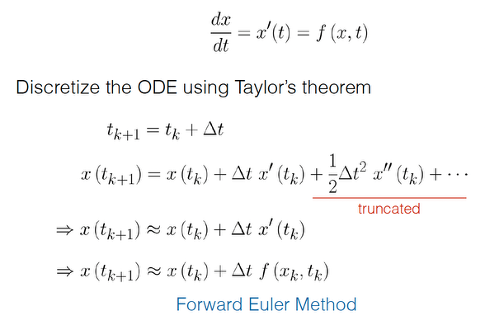

Using the forward Euler's method, we are basically forward differencing the ordinary differential equation:

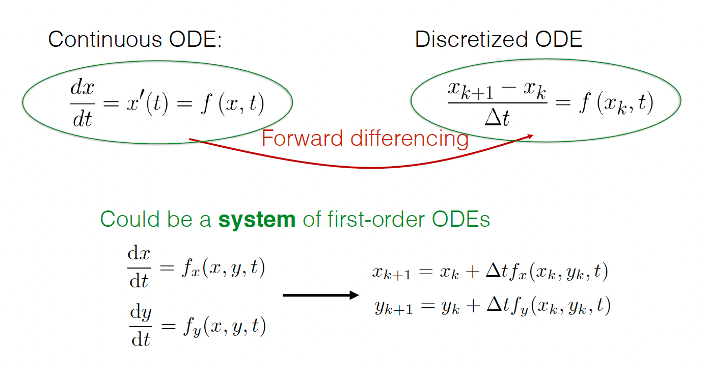

Returning to Lotka–Volterra equation:

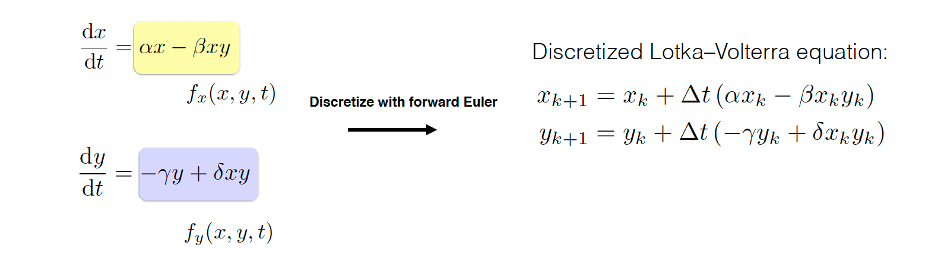

Above is called a difference equation. We can solve it by discretizing with Euler's method - given state at time $t_k$, return state at time $t_{k+1} =t_k +\Delta t$

***Ask Copilot:*** To demonstrate the errors introduced by discretized equations, we can generate code with the previously mentioned feature of MATLAB Copilot, Generate/Modify Code! In the code block below, copy and paste this prompt in, to see the analytical and numerical solutions for the differential eqution $\frac{\textrm{dx}}{\textrm{dt}}=x$.

Prompt suggested: "Generate a compact MATLAB script that compares x(t)=exp(t) with a forward-Euler discretization x_{k+1}=x_k + x_k*dt. The user has input dt (stored as a variable already); build `time = 0:dt:10`; compute `exact_curve = exp(time)`; compute `approx_curve` in a loop with `approx_curve(1)=1.0`; plot exact as solid blue (LineWidth 2) and approx as red dashed with circle markers (LineWidth 1.5); add legend ('Continuous (Exact)', 'Discretized (Approx)'), title 'Visualizing the Discretization Error', axis labels, and grid. Keep code compact and commented; use only base MATLAB."

If you like the code suggested, you can confrim it by clicking "Accept". Afterwards, run the code in this section.

dt=0.38 % This will allow you to dynamically change the time interval
% Prompt Copilot here!


Follow up questions:

- The code MATLAB Copilot generated should've plotted a graph visualizing the discretization error. What can you notice about the error over time, does it stay the same or does it get bigger? What do you think is responsible for this error?

- The discretized equation is consistently underapproximating the value. Why is this?

- Would the accuracy of the discretized equation increase if we used smaller time intervals (i.e. making `dt` a smaller value)? What is the tradeoff for using such an equation?

### MATLAB 2-D Line Plots

As you just produced a plot showcasing the errors introduced by discrete time, we'd like to take some time dedicated to learning how to plot functions in MATLAB. Suppose we want to plot a series of points each with x and y coordinates:

x = [0, 1, 2, 3, 4, 5];
y = [-1, 0, 1, 2, 1, 0];

`plot(x, y)` plots y versus x.

plot(x, y)

Since x and y are 1D arrays, MATLAB by default plots a line connecting the pairs of points `(x(1), y(1)), (x(2), y(2)), …, (x(N), y(N))`.

We can also plot just the points with, e.g., `plot(x, y, ’r.’)` (a red dot(‘.’)) 

Utilize the `help plot` command for more!

Whenever we are handling new concepts, instead of relying on the old workflow of revising documentation and other inefficient (but useful and detailed) resources, let's try to quickly grasp the general implementations of plotting functions using Ask Copilot.

***Ask Copilot: ***Using what you've learned about prompting Copilot, in the code section below create a script that plots two different oscillating datasets over 60 points. Both should be centered around a baseline of 30. Use a sine wave for one and a cosine wave for the other, but make sure they have different frequencies and line styles (like circles vs. squares) to experiment with plot stylization!

% Prompt Copilot here!


Scripts generated by Copilot can vary if the prompt isn't specific, but notice what lines you may not recognize the function of. What are the uses of "hold on" and "hold off"? How can we change the line style? We can utilize Copilot to explain code easily (another feature of MATLAB Copilot), via clicking the "Explain Code" button.

After creating the plot, we can format it to our specification. This is rather straightforward, so it is provided below - just keep in mind that a complete figure should include clear axis labels (with units when applicable), an informative title, an appropriate legend if multiple curves are shown, and readable tick marks and font sizes.

xlabel('Time')
ylabel('Population')
title('Two Populations over Time')
axis([0 30 20 40])
legend('Species A', 'Species B')

## Example Problem

### Populations of paramecium and yeast

The populations of the paramecium (predator) and yeast (prey) was modeled using Lotka–Volterra equation by Gause (1934) by experiments:


$$\frac{\textrm{dx}}{\textrm{dt}}=0\ldotp 65x-0\ldotp 04\textrm{xy}$$



$$\frac{\textrm{dy}}{\textrm{dt}}=-0\ldotp 32x+0\ldotp 05\textrm{xy}$$


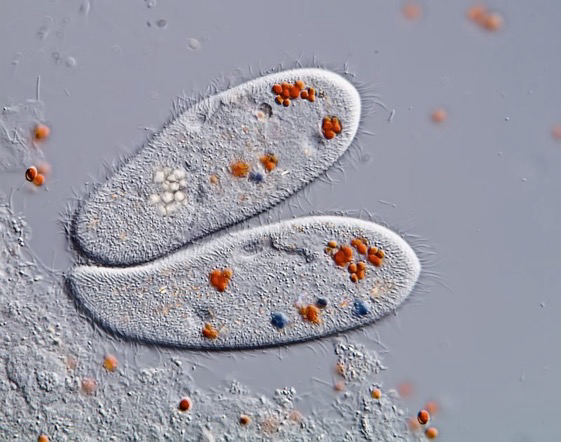

The initial population of prey (x) is **22** (per 0.5 c.c.) and predator (y) is **37** (per 0.1 c.mm.). Write a program using forward Euler method to calculate the population of these two species to t = 30. Use time step size Δt = 0.01.

This is an initial value ODE problem!

- Governing equations: $\frac{\textrm{dx}}{\textrm{dt}}=f\left(x,y\right)$, $\frac{\textrm{dy}}{\textrm{dt}}=g\left(x,y\right)$

- Initial condition: $x\left(0\right)=x_{o\;}$, $y\left(0\right)=y_{o\;}$

- We need to find: $x\left(t\right)$ and $y\left(t\right)$ for $0<t<t_f$.

So let's do it in a discrete manner:

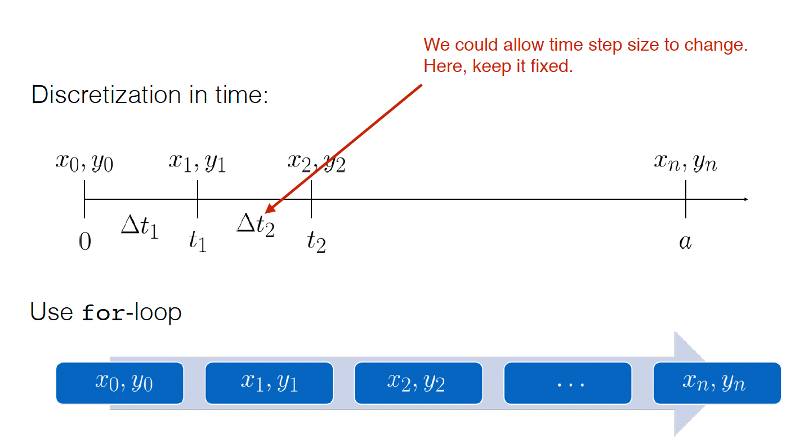

### Population ODE Pseudocode

% Set parameters alpha, beta, gamma, delta

% Set time step size delta_t, final time t_f

% Calculate number of time steps, m=ceil(t_f/delta_t)

% Set initial condition for x_old and y_old

% for k = 1:m

%      x <- (1+alpha*delta_t)*x - beta*delta_t*x*y
%      y <- (1-gamma*delta_t)*y + delta*delta_t*x*y
%      Data output

% end

There is an error in the above implementation! Can you identify what the error is? (Reference the Lotka–Volterra equations)

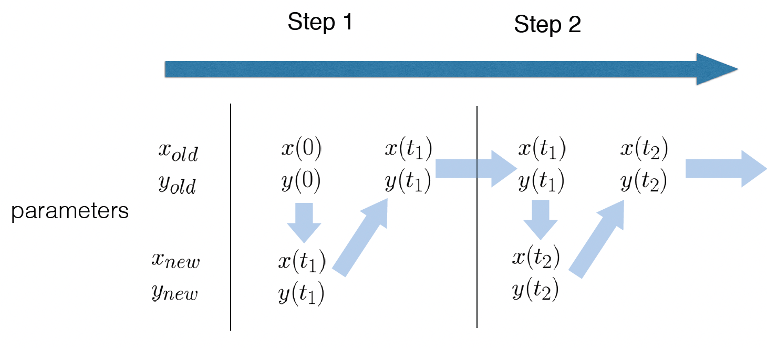

Now you can try "Three species competing for food" in the first homework problem!

## Topic 2: Pocket Change with Iteration

Our goal is to develop an algorithm to calculate the average number of coins you can expect to receive in your change after a cash transaction. The possible cent amounts you’d receive in change fall in the range [00, 01, 02, …, 99]. Our script must calculate the minimum number of coins required to form each amount, then compute the average.

### Example Calculation

Q: How would you form 58 cents using the minimum total number of the following coins?

     [Please use Quarter = 25, Dime = 10, Nickel = 5, Cent = 1]

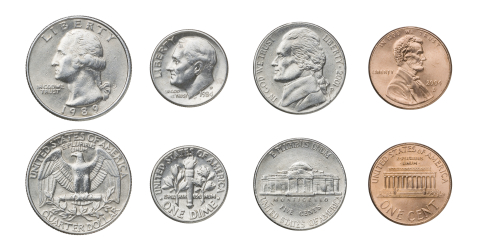

So your answer is probably 2*Quarter + 1*Nickel + 3*Cent. I know it is pretty easy to do “by hand”, so let’s try writing an algorithm.

### Pocket Change Pseudocode

% Change = 58
% CoinCount = 0

% while Change > 0 && CoinCount < 100 [Note: CoinCount < 100 is “safety
% net” to avoid an infinite loop is a good idea when iterating with while.]

    % Subtract the maximum possible coin from Change

    % CoinCount = CoinCount + 1

% end

If we can do it for the hard-coded case of Change = 58, how do we apply this logic to all amounts in the range [00, 01, 02, …, 99]? ---> ***HW: Pocket ******C******hange Problem - Part (a)***

What happens if we remove pennies from circulation? That is, we only consider forming cent amounts in the range [00, 05, 10, …, 95]. ---> ***HW: Pocket Change Problem - Part (b)***

### Pocket Change Optimization

Now that we’ve coded the basics, we can try a different experiment - what happens if we change the value(s) of the 4 existing coins? What denominations result in the lowest average number of coins in your change? --> ***HW: Pocket Change Problem - Part (c), HW: Pocket Change Problem - Part (d).***

***Ask Copilot:*** Consider a coin system with four denominations arranged from smallest to largest. We want the greedy algorithm (always take the largest possible coin first) to always give the best possible result. Create an example of four coin denominations where greedy does **not** give the smallest number of coins for some amount, and use one amount to show this failing case.

% Guiding question for the Pocket Change Problem (c) & (d)


Notice that we have been using the "Generate/Modify Code" feature from Ask Copliot today. Here are some follow up questions:

- Does your prompt fit better for Ask Copliot or in the sidebar of Copilot Chat? What are the differences in the output? Would this prompt have worked better in the Ask Copilot?

- Always aim to use Copilot as a learning tool! What are limitations of the features you have seen so far?